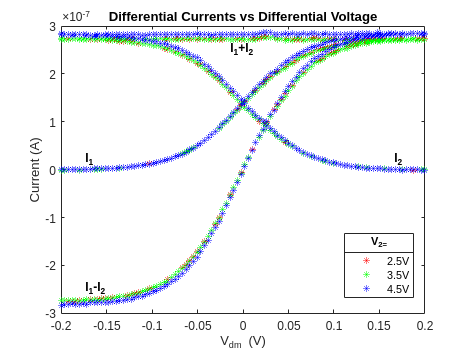

clear
load("sidak.mat")
epsil=5e-3;
diff_2_5=I1in_2_5 - I2in_2_5;
sum_2_5=I1in_2_5 + I2in_2_5;
diff_3_5=I1in_3_5 - I2in_3_5;
sum_3_5=I1in_3_5 + I2in_3_5;
diff_4_5=I1in_4_5 - I2in_4_5;
sum_4_5=I1in_4_5 + I2in_4_5;

figure()
p1 = plot(Vdm_2_5, I1in_2_5, "r*"); hold on
plot(Vdm_2_5, I2in_2_5, "r*");
plot(Vdm_2_5, sum_2_5, "r*");
plot(Vdm_2_5, diff_2_5, "r*");

p2 = plot(Vdm_2_5, I1in_3_5, "g*");
plot(Vdm_2_5, I2in_3_5, "g*");
plot(Vdm_2_5, sum_3_5, "g*");
plot(Vdm_2_5, diff_3_5, "g*");

p3 = plot(Vdm_2_5, I1in_4_5, "b*");
plot(Vdm_2_5, I2in_4_5, "b*");
plot(Vdm_2_5, sum_4_5, "b*");
plot(Vdm_2_5, diff_4_5, "b*");
hold off
xlabel("V_{dm} (V)")
ylabel("Current (A)")
lgd=legend([p1 p2 p3], {'2.5V', '3.5V', '4.5V'}, Location="best");
title("Differential Currents vs Differential Voltage")
title(lgd, 'V_2=')

text_x1 = -0.175;
text_y1 = -2.5e-7;
text_x2 = -0.175;
text_y2 = 0.2e-7;
text_x3 = 0.165;
text_y3 = 0.2e-7;
text_x4 = -0.015;
text_y4 = 2.5e-7;

text(text_x1, text_y1, 'I_{1}-I_{2}', 'FontSize', 10,'FontWeight','bold', 'Color', 'k');
text(text_x2, text_y2, 'I_{1}', 'FontSize', 10,'FontWeight','bold', 'Color', 'k');
text(text_x3, text_y3, 'I_{2}', 'FontSize', 10,'FontWeight','bold', 'Color', 'k');
text(text_x4, text_y4, 'I_{1}+I_{2}', 'FontSize', 10,'FontWeight','bold', 'Color', 'k');
print("-depsc","figures/12plots.eps")

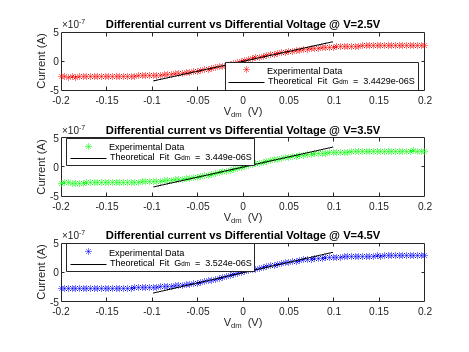



linear_idx = Vdm_2_5 >= -0.1 & Vdm_2_5 <= 0.1;
lin_2_5=diff_2_5(linear_idx);
lin_3_5=diff_3_5(linear_idx);
lin_4_5=diff_4_5(linear_idx);
lin_vdm=Vdm_2_5(linear_idx);


[f1, l1, m1, b1, n1] = linefit(lin_vdm, lin_2_5, epsil);
fitline1 = m1 * lin_vdm + b1;

[f2, l2, m2, b2, n2] = linefit(lin_vdm, lin_3_5, epsil);
fitline2 = m2 * lin_vdm + b2;

[f3, l3, m3, b3, n3] = linefit(lin_vdm, lin_4_5, epsil);
fitline3 = m3 * lin_vdm + b3;


figure();


subplot(3, 1, 1); 
plot(Vdm_2_5, diff_2_5, "r*", 'DisplayName', 'Experimental Data');
hold on;
plot(lin_vdm, fitline1, "k", 'DisplayName', ['Theoretical Fit G_{dm} = ' num2str(m1) 'S']);
hold off;
title("Differential current vs Differential Voltage @ V=2.5V");
xlabel("V_{dm} (V)");
ylabel("Current (A)");
legend('Location', 'best');

% Subplot 2 for V=3.5
subplot(3, 1, 2); % 3 rows, 1 column, 2nd plot
plot(Vdm_2_5, diff_3_5, "g*", 'DisplayName', 'Experimental Data');
hold on;
plot(lin_vdm, fitline2, "k", 'DisplayName', ['Theoretical Fit G_{dm} = ' num2str(m2) 'S']);
hold off;
title("Differential current vs Differential Voltage @ V=3.5V");
xlabel("V_{dm} (V)");
ylabel("Current (A)");
legend('Location', 'best');

% Subplot 3 for V=4.5
subplot(3, 1, 3); % 3 rows, 1 column, 3rd plot
plot(Vdm_2_5, diff_4_5, "b*", 'DisplayName', 'Experimental Data');
hold on;
plot(lin_vdm, fitline3, "k", 'DisplayName', ['Theoretical Fit G_{dm} = ' num2str(m3) 'S']);
hold off;
title("Differential current vs Differential Voltage @ V=4.5V");
xlabel("V_{dm} (V)");
ylabel("Current (A)");
legend('Location', 'best');

% Save the figure as EPS
print("-depsc","figures/diffcur_all.eps");

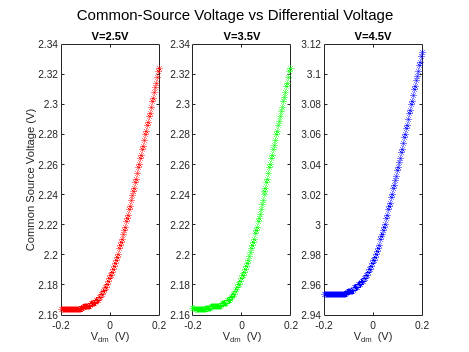

figure();

figure();
subplot(1, 3, 1);
plot(Vdm_2_5, V_2_5, "r*", 'DisplayName', "2.5V");
xlabel("V_{dm} (V)");
ylabel("Common Source Voltage (V)");
title("V=2.5V");

subplot(1, 3, 2);
plot(Vdm_2_5, V_3_5, "g*", 'DisplayName', "3.5V");
xlabel("V_{dm} (V)");
title("V=3.5V");

subplot(1, 3, 3)
plot(Vdm_2_5, V_4_5, "b*", 'DisplayName', "4.5V");
xlabel("V_{dm} (V)");
title("V=4.5V");
sgtitle('Common-Source Voltage vs Differential Voltage');